# Preprocess and Explore Data

## Represent data in MATLAB

 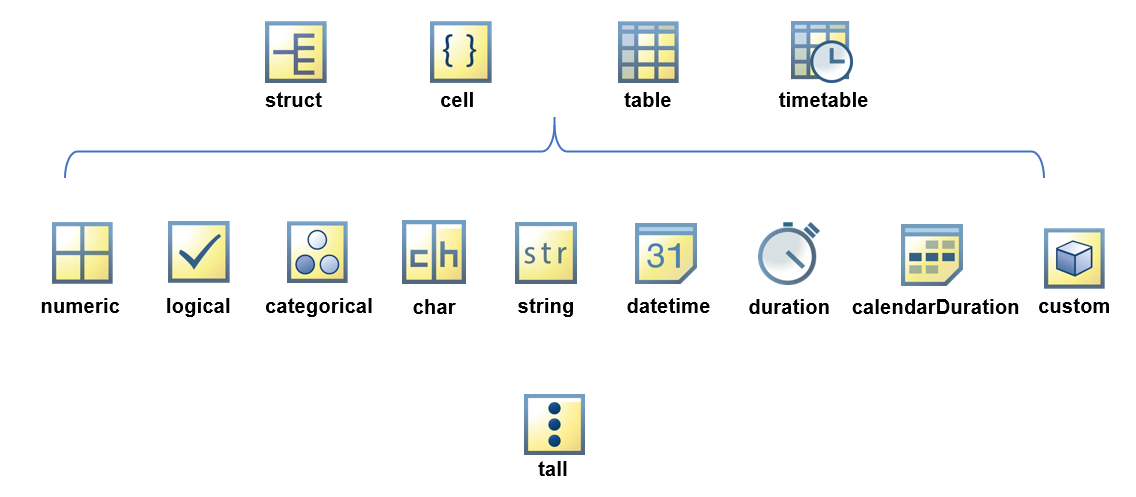

[https://www.mathworks.com/help/matlab/data-types.html](https://www.mathworks.com/help/matlab/data-types.html)

Load the data from the previous step

load PreprocessedData\rawData.mat
data

data = 147162×13 table
     event_id      state         event_type         begin_timestamp       end_timestamp      damage_property    damage_crops           source            begin_lat    begin_lon      end_lat      end_lon                                                                                                                 event_narrative                                                                                                           
    __________    ________    _________________    _________________    _________________    _______________    ____________    _____________________    _________    __________    _________    __________    _____________________________________________________________________________________________________________________________________________________________________________________________________________________________________

    7.5316e+05    NEBRASKA    Hail                 06-6月-18 18:10:00    06-6月-18 18:10:00       "0.00K

## Select data of interest 筛选数据

addpath('Helpers\')
SelectRearrangeData; %使用 Helpers 目录下的脚本，筛选数据

## Preprocess data by type 预处理数据

### Clean up times and determine storm duration 检查风暴持续时间

PreprocessByTime; %时间戳数据的预处理与重组

tmin = datetime
   01-1月-2018 00:00:00


tmax = datetime
   30-4月-2020 22:37:00


maxNumDays = 30.9993

avgDur = duration
   29:14:00


medDur = duration
   00:30:00


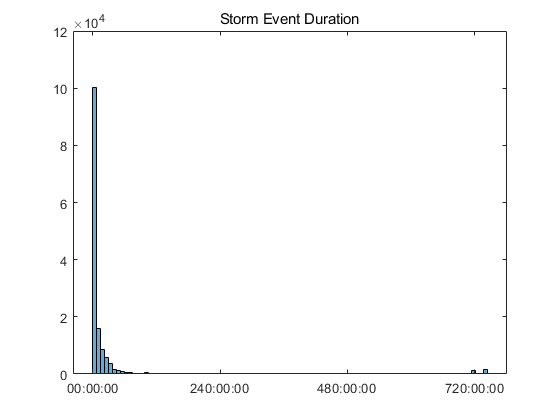

histogram(data.storm_duration) %持续时长直方图
title("Storm Event Duration")

The longest storm(s) lasted for a month! Examine these storms.

检查持续时长最长的十个风暴：

[maxDur,idx] = maxk(data.storm_duration,10); %查找持续时长 data.storm_duration 中最大的10个值
longestStormDur = data(idx,:)

longestStormDur = 10×10 timetable
            Time             state      event_type    damage_property    damage_crops    begin_lat    begin_lon    end_lat    end_lon    event_narrative    storm_duration
    ____________________    ________    __________    _______________    ____________    _________    _________    _______    _______    _______________    ______________

    01-1月-2018 00:00:00    MISSOURI     Drought          "0.00K"          "0.00K"          ""           ""          ""         ""             ""             743:59:00   
    01-1月-2018 00:00:00    MISSOURI     Drought          "0.00K"          "0.00K"          ""           ""          ""         ""             ""             743:59:00   
    01-1月-2018 00:00:00    ILLINOIS     Drought          "0.00K"          "0.00K"          ""           ""          ""         ""             ""             743:59:00   
    01-1月-2018 00:00:00    ILLINOIS     Drought          "0.00K"          "0.00K"          ""           ""       

### Combine similar storm categories 合并类似的风暴类别

head(data(:,vartype("categorical"))) %显示表中的 分类数组，head()函数使之只显示前几行

ans = 8×2 timetable
            Time             state      event_type
    ____________________    ________    __________

    01-1月-2018 00:00:00    MISSOURI     Drought  
    01-1月-2018 00:00:00    MISSOURI     Drought  
    01-1月-2018 00:00:00    ILLINOIS     Drought  
    01-1月-2018 00:00:00    ILLINOIS     Drought  
    01-1月-2018 00:00:00    MISSOURI     Drought  
    01-1月-2018 00:00:00    MISSOURI     Drought  
    01-1月-2018 00:00:00    MISSOURI     Drought  
    01-1月-2018 00:00:00    MISSOURI     Drought  


Visualize the event frequency (use the helper function `bigFigure` to see many categories)

可视化不同类别事件的频率（这里使用了 Helpers 目录下的 bigFigure 函数来创建足够高的figure来容纳多种类别）

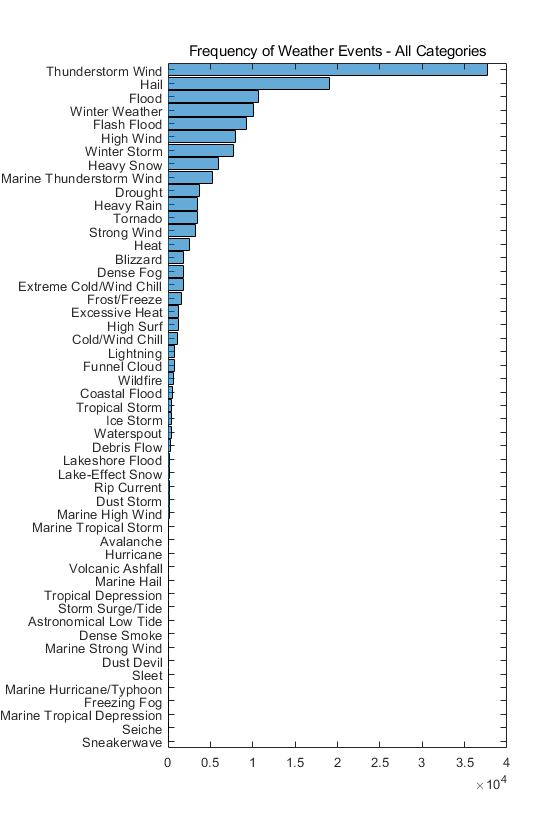

bigFigure("tall");
histogram(data.event_type,"Orientation","horizontal",...
    "DisplayOrder","ascend")
title("Frequency of Weather Events - All Categories")

Combine similar categories. 

合并相似的类别：

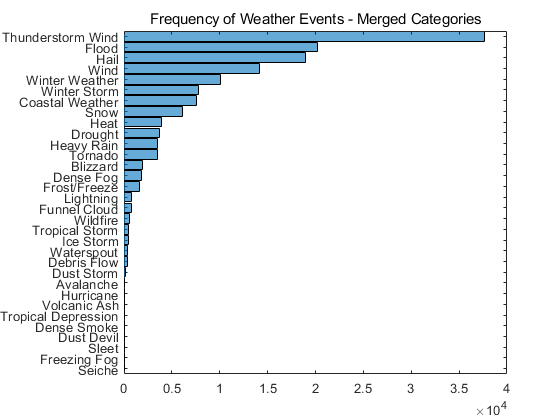

data = PreprocessCategories(data); %预处理，删除了一些"位置"的事件，合并了一些"类型"的事件
figure
histogram(data.weathercats,"Orientation","horizontal",...
    "DisplayOrder","ascend")
title("Frequency of Weather Events - Merged Categories")

### Convert text data to numeric 将文本数据转换为数字

Examine some random rows in the table to explore textual data.

随机从表中抽取几行，浏览文本数据。

datasample(data(:,vartype("string")),10)

ans = 10×7 timetable
            Time            damage_property    damage_crops    begin_lat    begin_lon      end_lat      end_lon                                                                                                                                                                event_narrative                                                                                                                                                           
    ____________________    _______________    ____________    _________    __________    _________    __________    _____________________________________________________________________________________________________________________________________________________________

Convert locations and the damage costs containing "K" and "M" with the correct units using the helper function, `PreprocessStrings.mlx`. 

使用辅助函数 `PreprocessStrings.mlx，`用正确的单位转换位置(经纬度)和包含“ K”“ M”的损坏成本。

data = PreprocessStrings(data);
head(data)

ans = 8×12 timetable
            Time             state      event_type    damage_property    damage_crops    begin_lat    begin_lon    end_lat    end_lon    event_narrative    storm_duration    weathercats    damage_total
    ____________________    ________    __________    _______________    ____________    _________    _________    _______    _______    _______________    ______________    ___________    ____________
    01-Jan-2018 00:00:00    MISSOURI     Drought             0                0             NaN          NaN        

## Explore data

Plot some of the events on a map and use the size of the bubble as the damage cost.

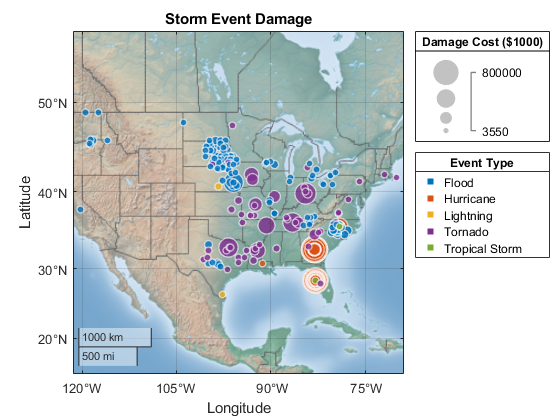

threshold = 3500;
plotEventCostsMap(data,threshold);

### Event frequency by location

Calculate damage costs by group.

damageByEvent = groupsummary(data,"weathercats",["mean","std"],"damage_total")

damageByEvent = 32×4 table
      weathercats      GroupCount    mean_damage_total    std_damage_total
    _______________    __________    _________________    ________________
    Avalanche               75              2.971              24.076     
    Blizzard              1883             10.108              112.62     
    Coastal Weather       7599             177.35              9347.8     
    Debris Flow            350             104.51              959.19     
    Dense Fog             1850            0.88366              8.9544     
    Dense Smoke             47                  0                   0     
    Drought               3718             6.4954              197.95     
    Dust Devil              18             37.313              123.99     
    Dust Storm             158             6.8027              46.316     
    Flood   

topdamage = topkrows(damageByEvent,10,"mean_damage_total")

topdamage = 10×4 table
      weathercats      GroupCount    mean_damage_total    std_damage_total
    _______________    __________    _________________    ________________
    Hurricane               70          1.3613e+05           2.2573e+05   
    Tornado               3525              1133.2                16679   
    Tropical Storm         460              1026.6               7107.1   
    Wildfire               621              809.58               5514.1   
    Flood                20225              273.96               4829.7   
    Coastal Weather       7599              177.35               9347.8   
    Frost/Freeze          1579              141.38               2564.9   
    Debris Flow            350              104.51               959.19   
    Ice Storm              418              96.603               528.32   
    Lightning   

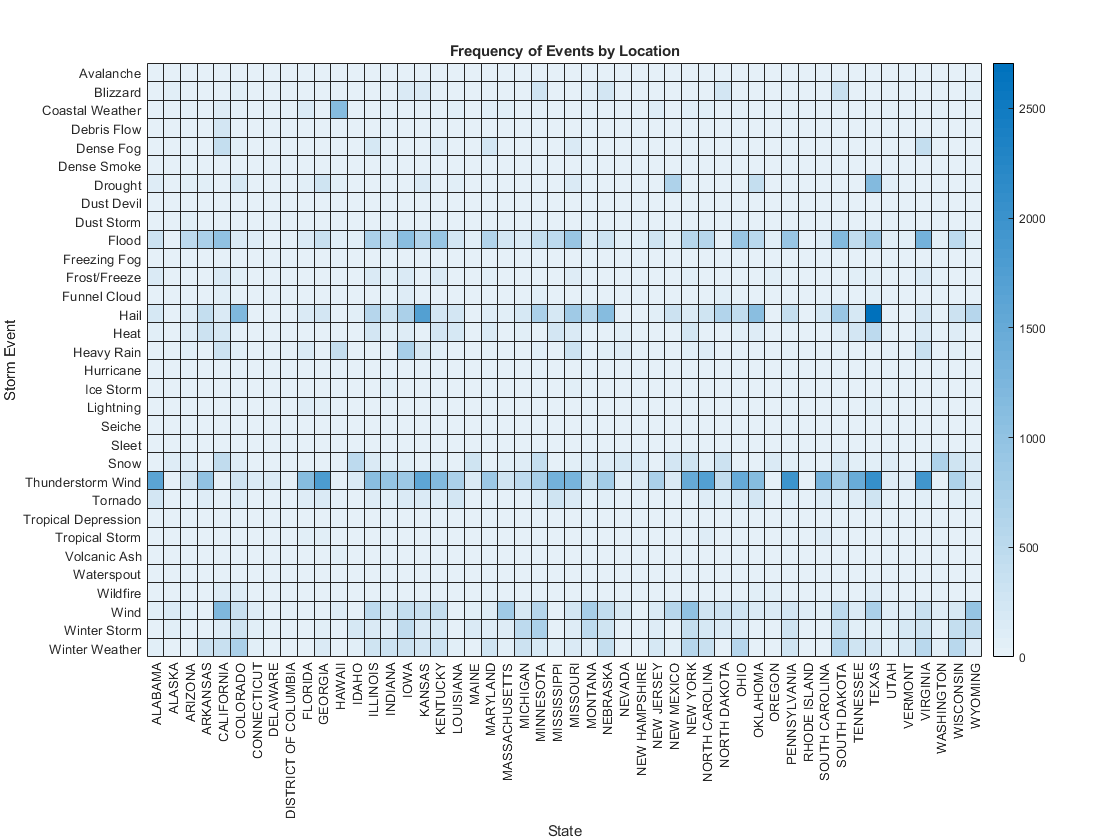

bigFigure;
heatmap(data,"state","weathercats"); 
xlabel("State")
ylabel("Storm Event")
title("Frequency of Events by Location")

### Compare damage cost by event and location

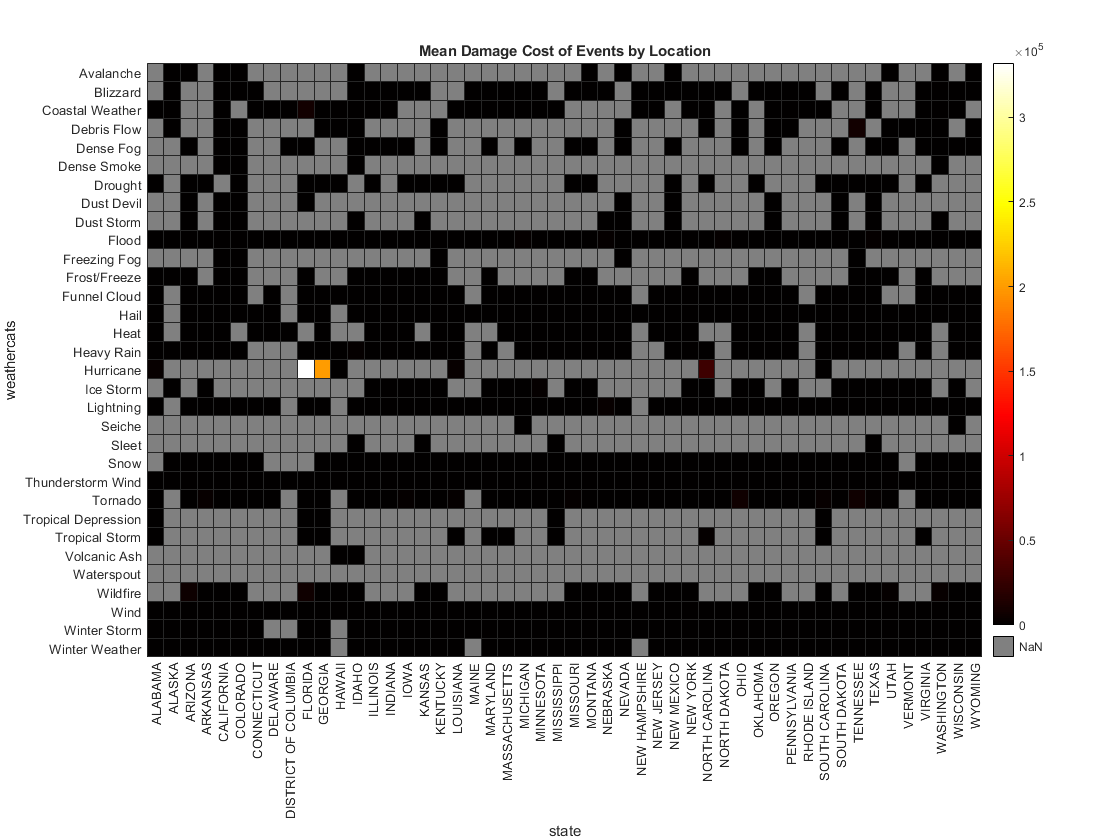

h = heatmap(data,"state","weathercats",...
    "ColorVariable","damage_total"); 
h.Colormap = hot;
h.MissingDataColor = [0.5 0.5 0.5];
title("Mean Damage Cost of Events by Location")

Explore damage costs with several visualizations.

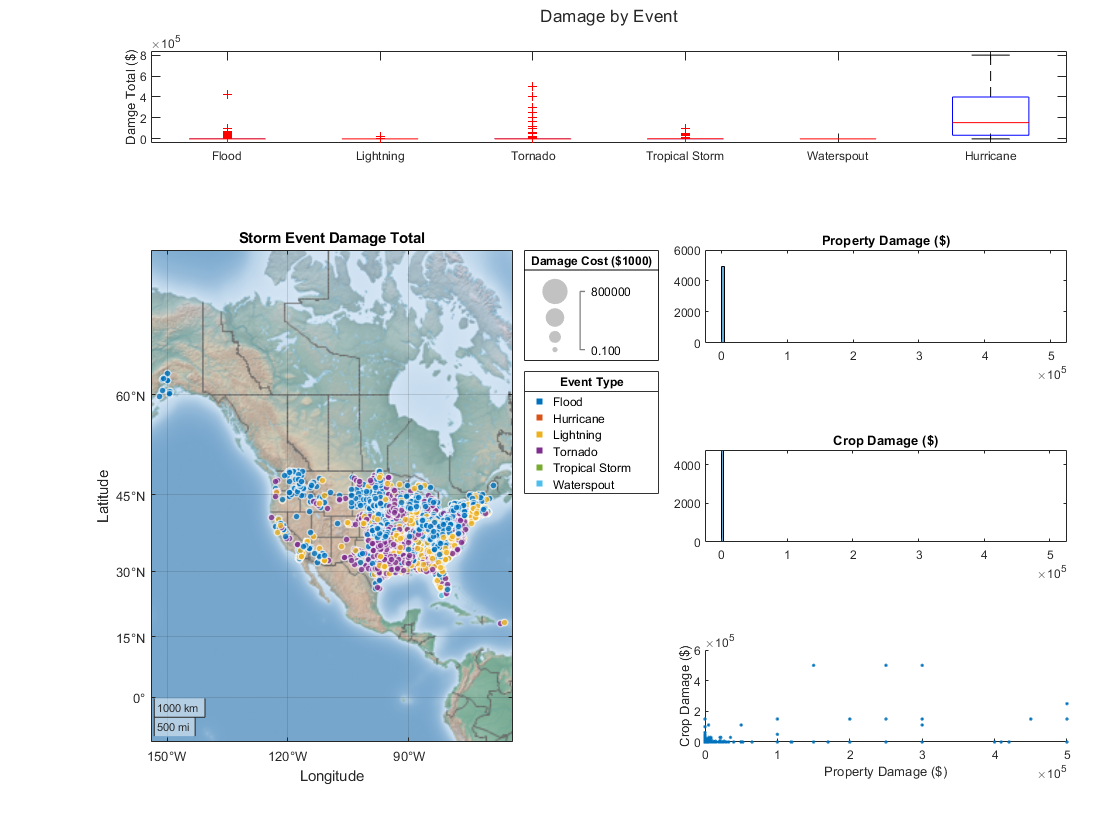

plotEventCosts(data)

### Explore event descriptions

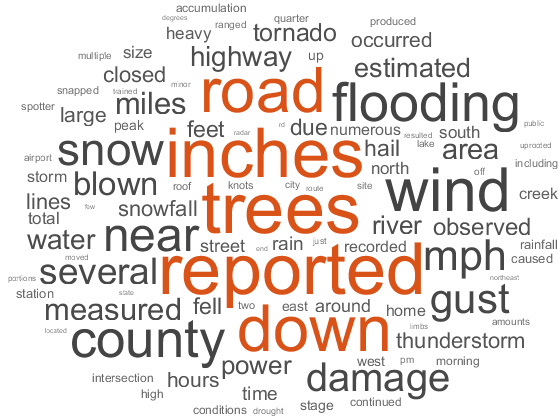

figure
wordcloud(data.event_narrative);

This indicates the most frequent events (wind, snow, flooding) and other related terms. Explore the text based on event type.

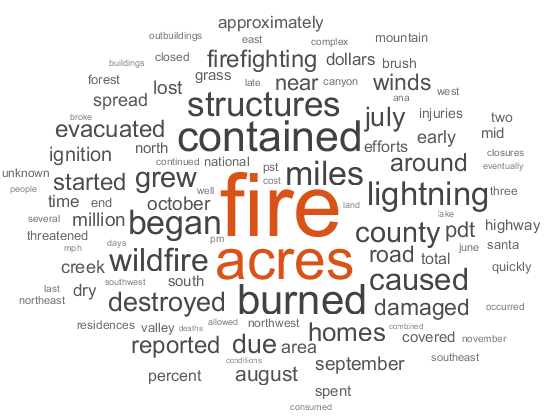

type = "Wildfire";

wordcloud(lower(data.event_narrative(data.event_type == type)));

## Work with missing data

There are missing data in a number of variables which may need different strategies. Various functions can help depending on your goals:

- `standardizeMissing`

- `ismissing`

- `rmmissing`

- `fillmissing`

Count the missing values in the table for each variable.

idx = ismissing(data);
sum(idx)

ans =         8638           0       28261       27720       55418       55418       55418       55418           0           0           0       25122


Remove rows with all missing data. 

data = rmmissing(data,"MinNumMissing",width(data));

Visualize the data set as a whole to allow us to see any remaining patterns of missing values using the function defined below.

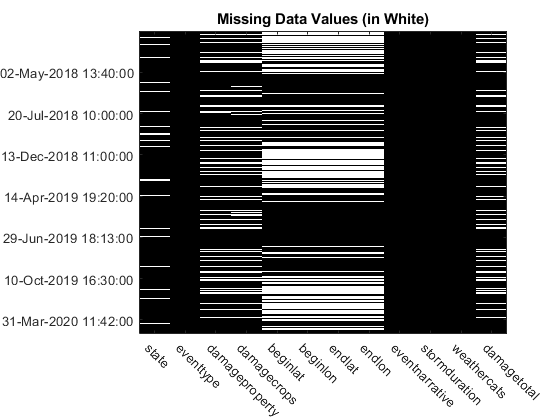

visualizeTableMask(data,idx);
title("Missing Data Values (in White)")

Some variables seem to have a significant number of missing values. 

Replace missing latitudes and longitudes with those of the US state.

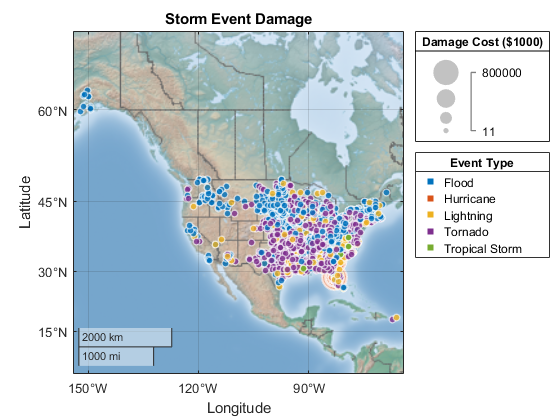

data = FillMissingLatLon(data);
plotEventCostsMap(data,10)

We may revisit additional strategies for the remaining missing data after exploring the data more thoroughly.

## Work with outliers

There are many outliers in this data set. Examine the ones in the damage costs.

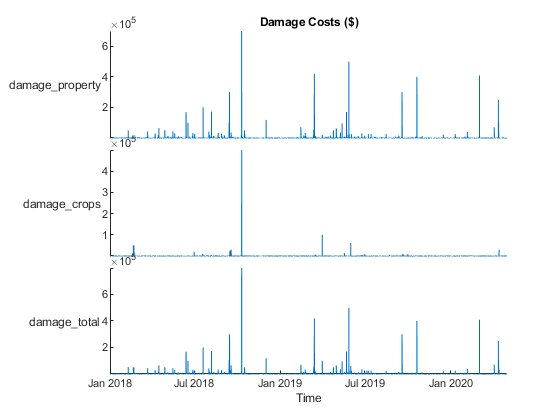

damage = data(:,startsWith(data.Properties.VariableNames,"damage_"));
stackedplot(damage);
title("Damage Costs ($)")

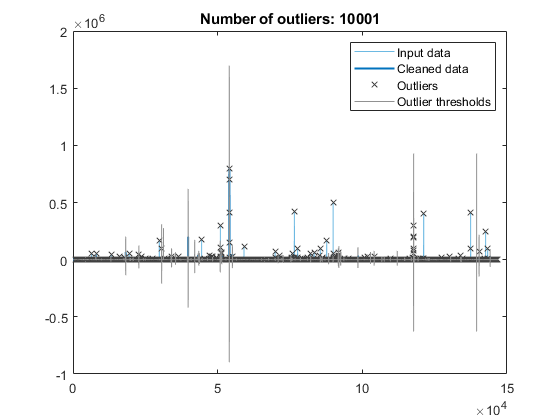

% Remove outliers
[cleanedData,outlierIndices] = rmoutliers(damage.damage_total,'movmedian',3,...
    'ThresholdFactor',3.5);

% Display results
clf
plot(damage.damage_total,'Color',[109 185 226]/255,'DisplayName','Input data')
hold on
plot(find(~outlierIndices),cleanedData,'Color',[0 114 189]/255,'LineWidth',1.5,...
    'DisplayName','Cleaned data')

% Plot outliers
plot(find(outlierIndices),damage.damage_total(outlierIndices),'x',...
    'Color',[64 64 64]/255,'DisplayName','Outliers')
title(['Number of outliers: ' num2str(nnz(outlierIndices))])

% Compute thresholds and center
[~,thresholdLow,thresholdHigh] = isoutlier(damage.damage_total,'movmedian',3,...
    'ThresholdFactor',3.5);

% Plot outlier thresholds
plot([(1:numel(damage.damage_total))'; missing; (1:numel(damage.damage_total))'],...
    [thresholdHigh(:); missing; thresholdLow(:)],'Color',[145 145 145]/255,...
    'DisplayName','Outlier thresholds')

hold off
legend

clear thresholdLow thresholdHigh

Do this for all damage costs and visualize.

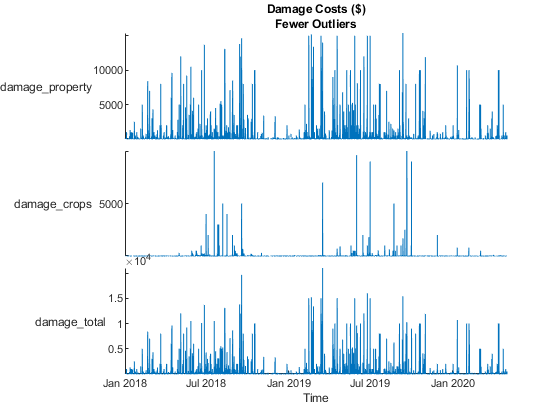

damage = rmoutliers(damage,"mean");
stackedplot(damage);
title(["Damage Costs ($)","Fewer Outliers"])

## Compare events to weather data

The script `compareLocalWeather` reads data from weather sensors at MathWorks headquarters in Natick, MA and synchronizes the weather data with the storm event data. Select the preprocessing steps to perform.

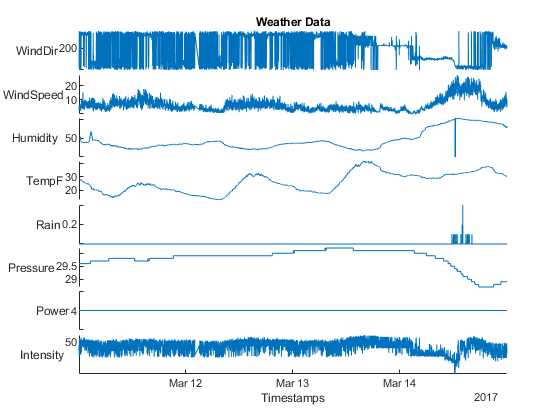

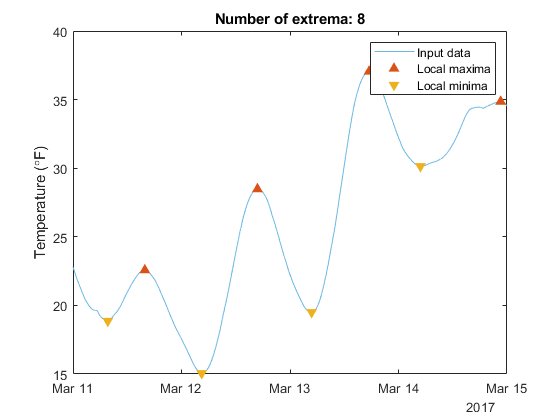

hiTemps = 4×8 timetable
         Timestamps         WindDir    WindSpeed    Humidity    TempF     Rain    Pressure    Power    Intensity
    ____________________    _______    _________    ________    ______    ____    ________    _____    _________
    11-Mar-2017 15:53:00    338.03       4.0968        27       23.913     0        29.8        4       44.871  
    12-Mar-2017 16:48:00      20.4          3.3        23        31.74     0        29.9        4         50.4  
    13-Mar-2017 17:30:00    259.11      0.28226        18       41.435     0        30.1        4           46  
    14-Mar-2017 22:36:00    232.02   

lowTemps = 4×8 timetable
         Timestamps         WindDir    WindSpeed    Humidity    TempF     Rain    Pressure    Power    Intensity
    ____________________    _______    _________    ________    ______    ____    ________    _____    _________
    11-Mar-2017 07:42:00    53.475      7.8098       29.426     15.043     0        29.8        4       50.738  
    12-Mar-2017 04:28:00    153.92      6.1738           39     14.685     0        29.9        4       40.443  
    13-Mar-2017 04:47:00       296      2.2306           41       18.6     0        30.1        4       46.177  
    14-Mar-2017 04:51:00    94.306  

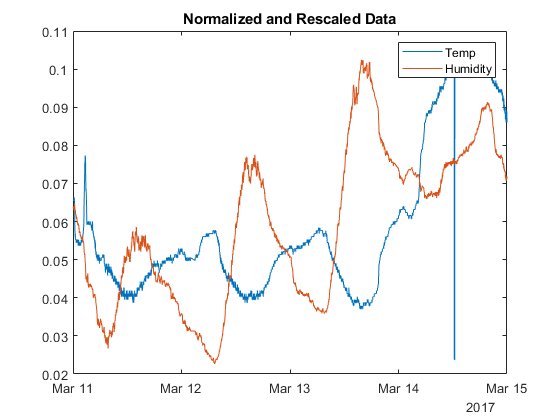

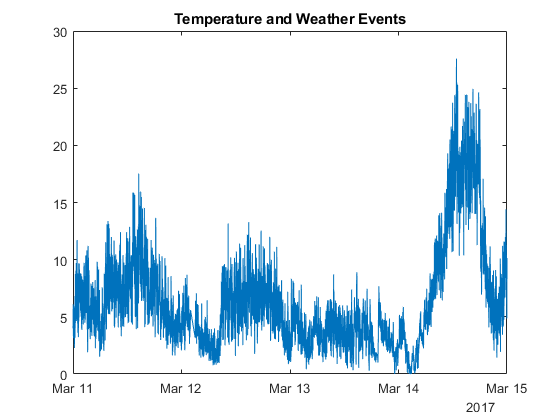

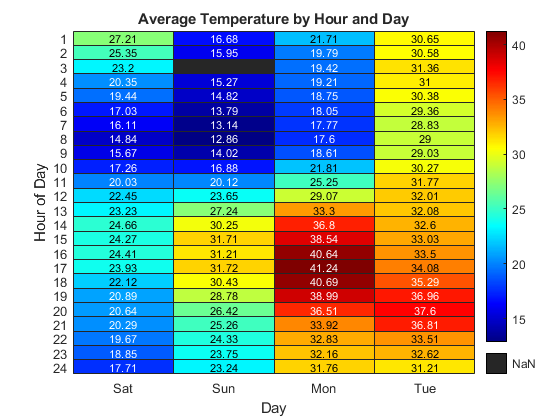

DetectFillOutliers = true;
DetectChangePoints = true;
NormalizeAndRescale = true;

CompareLocalWeather;

## Scale analysis

Repeat this analysis for data from all years since 1980 and get a sample of all data to build a model. See `PreprocessAllData.mlx` for details.

## Predict damage costs

Follow the script `PredictDamageCosts.mlx` to build a machine learning model (using the Regression Learner app) to predict the costs of events.

edit PredictDamageCosts

## Create Web App

Now this model can be used in an app to predict cost based on these variables. See `CreateWebApplication.mlx`

% EventDamageCosts

**Helper functions**

function visualizeTableMask(data,idx)
figure
imagesc(idx)
xticklabels(erase(data.Properties.VariableNames,"_"))
xticks(1:width(data))
xtickangle(-45)
ys = yticks;
yticklabels(cellstr(data.Time(ys)))
colormap gray
end

function plotEventCostsMap(data,threshold)
ev = ["Flood","Lightning","Tropical Storm","Hurricane",...
    "Waterspout","Tornado"];
idx = ismember(string(data.event_type),ev) & ...
    data.damage_total > threshold;
x = data(idx ,:);
x.weathercats = removecats(x.weathercats);
x = FillMissingLatLon(x);
figure
gb = geobubble(x,"begin_lat","begin_lon",...
    "SizeVariable","damage_total","ColorVariable","weathercats");
gb.Title = "Storm Event Damage";
gb.SizeLegendTitle = "Damage Cost ($1000)";
gb.ColorLegendTitle = "Event Type";
gb.Basemap = "colorterrain";
end

function data = FillMissingLatLon(data)
stateLatLon = struct2table(shaperead("usastatehi"));
idx = find(ismissing(data.begin_lat) & ismissing(data.begin_lon) & ~ismissing(data.state) & ...
    ismember(string(data.weathercats),["Tropical Storm","Hurricane",...
    "Waterspout"]));
for ii = 1:length(idx)
    sidx = lower(stateLatLon.Name) == lower(string(data.state(idx(ii))));
    data.begin_lat(idx(ii)) = stateLatLon.LabelLat(sidx);
    data.begin_lon(idx(ii)) = stateLatLon.LabelLon(sidx);
end
end

function plotEventCosts(data)
ev = ["Flood","Lightning","Tropical Storm","Hurricane",...
    "Waterspout","Tornado"];
idx = ismember(string(data.event_type),ev) & ...
    data.damage_total > 0;
x = data(idx ,:);
x.weathercats = removecats(x.weathercats);
warning("off","MATLAB:handle_graphics:Layout:NoPositionSetInTiledChartLayout")
% Create figure
t = tiledlayout(4,2,"TileSpacing","compact","Padding","compact");  %#ok
nexttile([1 2])
boxplot(x.damage_total,x.event_type)
ylabel("Damge Total ($)")
nexttile(3,[3 1])
gb = geobubble(x,"begin_lat","begin_lon",...
    "SizeVariable","damage_total","ColorVariable","weathercats");
gb.Title = "Storm Event Damage Total";
gb.SizeLegendTitle = "Damage Cost ($1000)";
gb.ColorLegendTitle = "Event Type";
gb.Basemap = "colorterrain";
nexttile
histogram(x.damage_property)
title("Property Damage ($)")
nexttile
histogram(x.damage_crops)
title("Crop Damage ($)")
nexttile
scatter(x.damage_property,x.damage_crops,".");
xlabel("Property Damage ($)"); ylabel("Crop Damage ($)")
sgtitle("Damage by Event")
warning("on","MATLAB:handle_graphics:Layout:NoPositionSetInTiledChartLayout")
end

*Copyright 2018 - 2020 The MathWorks, Inc.*